# ** GRN Project 2**

Five gene regulatory network motifs are simulated in the code `GRNs_for_HW2.m`. These are:

- Direct negative feedback

- Indirect negative feedback

- Double negative feedback

- Incoherent feed-forward

- Repressilator

For most gene regulatory motifs, as an activating input is increased, the steady-state amount of protein increases gradually. The *biological function* of "ultrasensitivity" or "switch-like response" is a phenomena where the steady-state amount of protein increases slowly, then suddenly, then slowly again. 

# HW2 

Find at least one of the 5 network motifs listed above that produces a switch-like response. Plot the amount of protein as a function of input concentration, showing the switch-like graph.

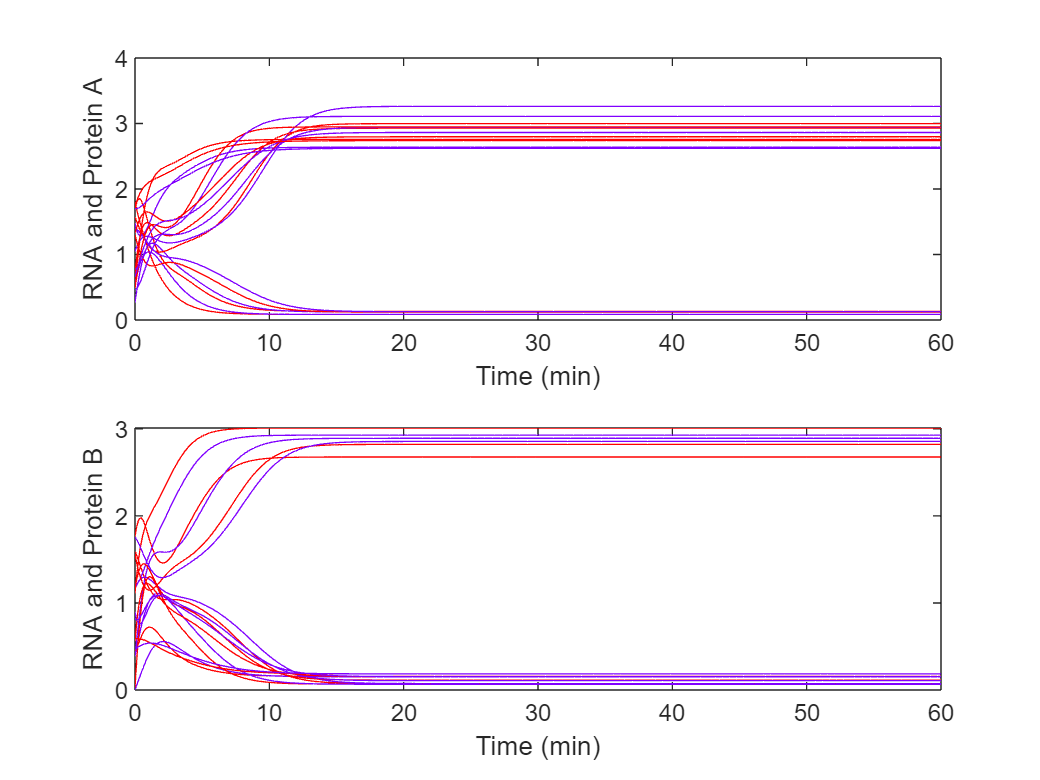

%% 5.0 ----- DOUBLE NEGATIVE FEEDBACK -----

noisiness = 0.1;
noisiness2 = 0.1;

figure(); clf; 

numRuns = 1000;
storage_A = zeros(1,numRuns);
storage_B = zeros(1,numRuns);

          
for iRun = 1:numRuns
                    
    delta_ma = 1*(1+noisiness*rand());
    gamma_pa = 1*(1+noisiness*rand());
    delta_pa = 1*(1+noisiness*rand());
    
    delta_mb = 1*(1+noisiness*randn());
    gamma_pb = 1*(1+noisiness*rand());
    delta_pb = 1*(1+noisiness*rand());
    
    Kba = 1*(1+noisiness2*randn()); % Strength (IC50^-1) of inhibition of A by B
    Kaa = 0;
    gamma_ma =@(pb) 3./(1+abs(Kba*pb).^3);
    
    Kab = 1*(1+noisiness2*randn()); % Strength (IC50) of inhibition of B by A
    Kbb = 0;
    gamma_mb =@(pa) 3./(1+abs(Kab*pa).^3);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pb) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;
    
    dmbdt =@(ma,pa,mb,pb,t) +gamma_mb(pa) - delta_mb*mb;
    dpbdt =@(ma,pa,mb,pb,t) +gamma_pb*mb - delta_pb*pb;

    dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),t);
                  dpadt(x(1),x(2),x(3),x(4),t);
                  dmbdt(x(1),x(2),x(3),x(4),t);
                  dpbdt(x(1),x(2),x(3),x(4),t)];
    
    
    initialCondition = 2*rand(4,1);
    

    [T, X] = ode45(dxdt, [0.0,60], initialCondition);

    if iRun<10
        subplot(2,1,1);hold on; box on;
        plot(T,X(:,1),'-r'); % red for RNA
        plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple
        ylabel('RNA and Protein A')
        xlabel('Time (min)')

        subplot(2,1,2);hold on; box on;
        plot(T,X(:,3),'-r'); % red for RNA
        plot(T,X(:,4),'-', 'color', [0.5 0 1]); % purple
        ylabel('RNA and Protein B')
        xlabel('Time (min)')
    end

    storage_A(iRun) = X(end,2);
    storage_B(iRun) = X(end,4);
    
end

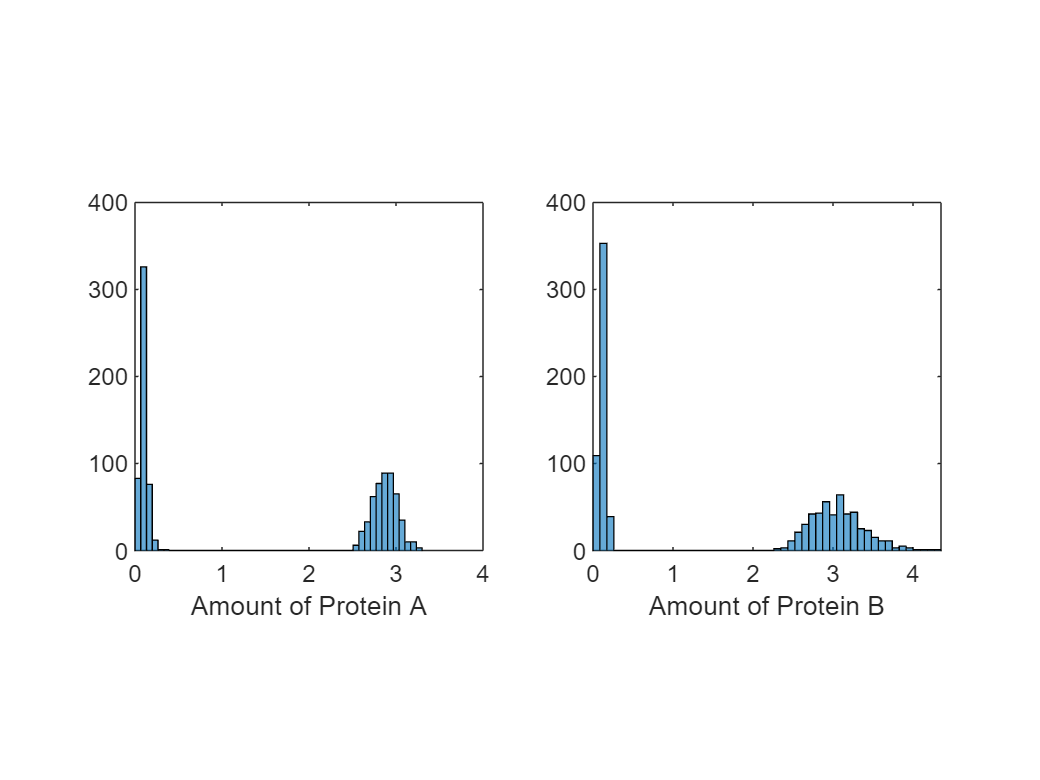


figure(); clf; 
subplot(1,2,1); hold on; box on;
axis square
histogram(storage_A, 50);
xlabel('Amount of Protein A')

subplot(1,2,2); hold on; box on;
axis square
histogram(storage_B,50);
xlabel('Amount of Protein B')

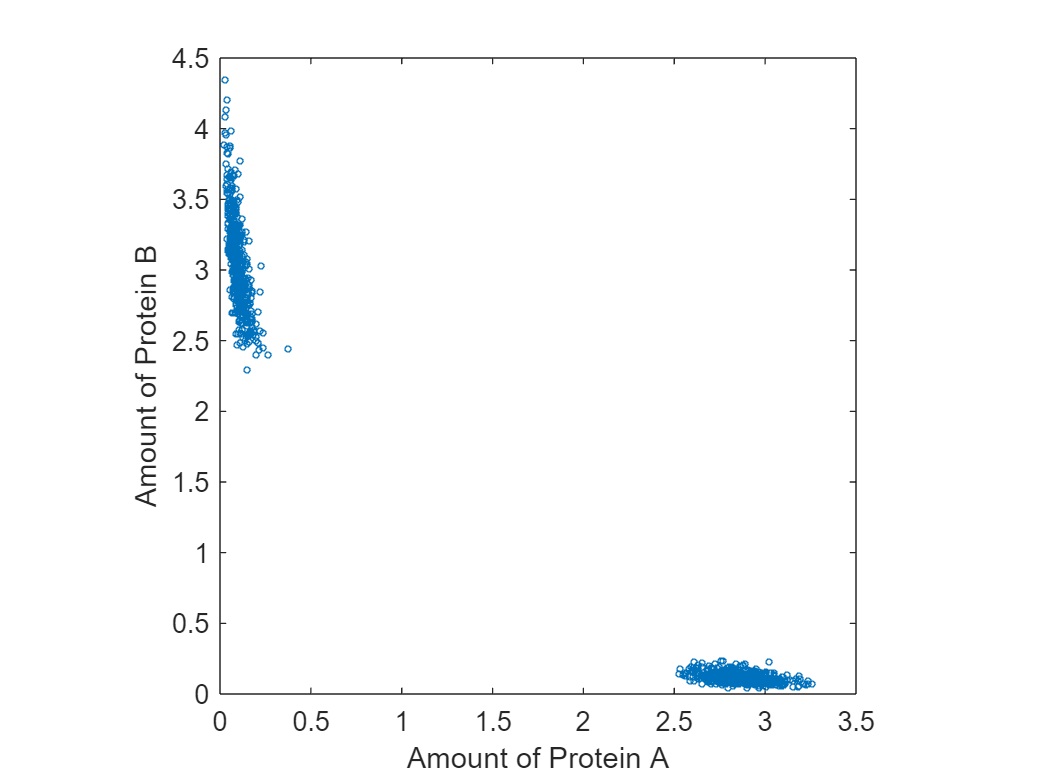


figure(); hold on; box on;
axis square
scatter(storage_A,storage_B,5);
xlabel('Amount of Protein A')
ylabel('Amount of Protein B')